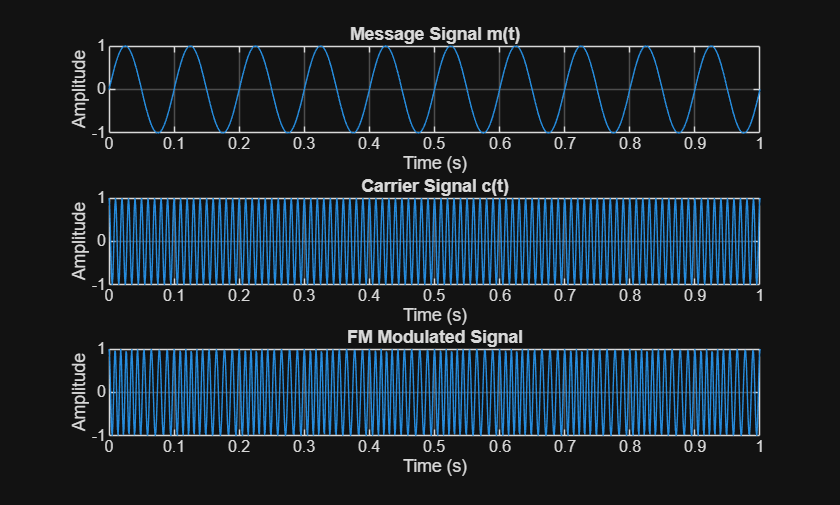

clear all;
close all;
clc;

% --- Parameters ---
fc = 100;    % Carrier frequency (Hz)
fm = 10;     % Message signal frequency (Hz)
kf = 20;     % Frequency deviation constant (Hz/Volt) - related to modulation index
Fs = 1000;   % Sampling frequency (Hz)
T = 1/Fs;    % Sampling period
t = 0:T:1;   % Time vector (1 second duration)

% --- Message Signal (Modulating Signal) ---
Am = 1;      % Amplitude of message signal
m_t = Am * sin(2*pi*fm*t);

% --- Carrier Signal ---
Ac = 1;      % Amplitude of carrier signal
c_t = Ac * cos(2*pi*fc*t);

% --- FM Modulation ---
% The instantaneous frequency of the FM signal is given by:
% fi(t) = fc + kf * m(t)
% The phase of the FM signal is the integral of the instantaneous frequency:
% phi(t) = 2*pi*fc*t + 2*pi*kf * integral(m(tau) d_tau)
% The FM signal is then:
% s_fm(t) = Ac * cos(phi(t))

% Calculate the integral of the message signal
int_m_t = cumsum(m_t) * T; % Numerical integration using cumulative sum

% Generate the FM signal
s_fm_t = Ac * cos(2*pi*fc*t + 2*pi*kf * int_m_t);

% --- Plotting ---
figure;

subplot(3,1,1);
plot(t, m_t);
title('Message Signal m(t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(t, c_t);
title('Carrier Signal c(t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(t, s_fm_t);
title('FM Modulated Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;